# Processing Data Samples from MRI

Reference - J. Appl. Phys. 105, 004904  (2009)

## 1. Ultra Wide Band Signal Characteristics

Taken from the Ultra-Wide band signal paper here

[http://digitalcommons.unl.edu/cgi/viewcontent.cgi?article=1058&context=computerelectronicfacpub](http://digitalcommons.unl.edu/cgi/viewcontent.cgi?article=1058&context=computerelectronicfacpub)

[http://www.mathworks.com/matlabcentral/fileexchange/37648-generation-of-uwb-pulse?focused=5238039&tab=function](http://www.mathworks.com/matlabcentral/fileexchange/37648-generation-of-uwb-pulse?focused=5238039&tab=function)

**General zero-mean Gaussian Pulse**


$$p_G \left(t\right)=\mathrm{exp}\left(-2\pi \frac{t^2 }{\tau^2 }\right)$$


**Ricker Pulse (Second Derivative of Gaussian)**


$$\begin{array}{l}
p_G \left(t\right)=\left(2\beta -1\right)\mathrm{exp}\left(-\beta \right)\\
\beta =2\pi \frac{t^2 }{{\tau_0 }^2 }
\end{array}$$


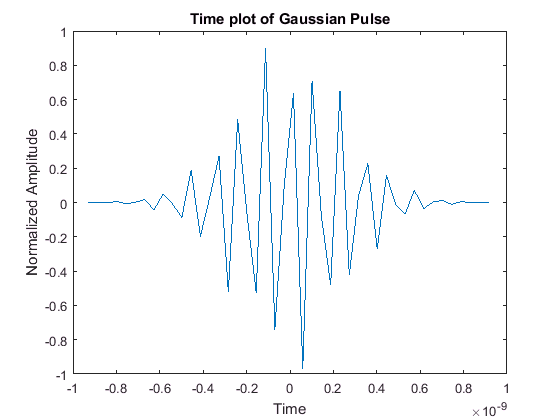

clc; clear;

Fs = 23.328e9; % Samples per second
Bw = 1.5e9;

% Using the Xethru Ultra Wideband Pulse
center_freq = 8.748e9;
tc = gauspuls('cutoff',center_freq,Bw/center_freq,[],-60); 
t = -tc : 1/Fs : tc; 
s_tx = gauspuls(t,center_freq,Bw/center_freq); 
figure;
plot(t,s_tx)

title('Time plot of Gaussian Pulse')
xlabel('Time')
ylabel('Normalized Amplitude')

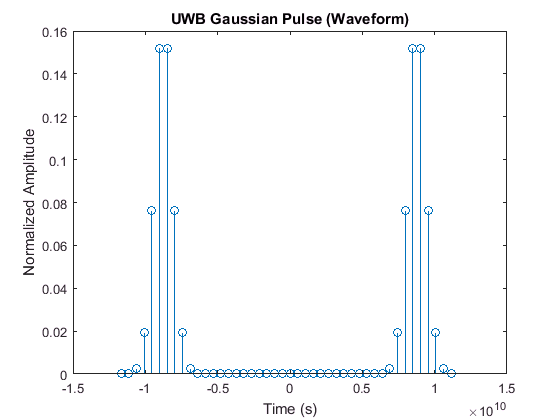


n = length(t);
f = Fs*(-n/2:n/2-1)/n;
S_tx = fftshift(fft(s_tx))/n;
stem(f, abs(S_tx));

title('UWB Gaussian Pulse (Waveform)')
xlabel('Time (s)')
ylabel('Normalized Amplitude')


clear beta fftPulse L P1 P2 pulse tao tc n

## 2. Combination of Multiple Physiological Signatures

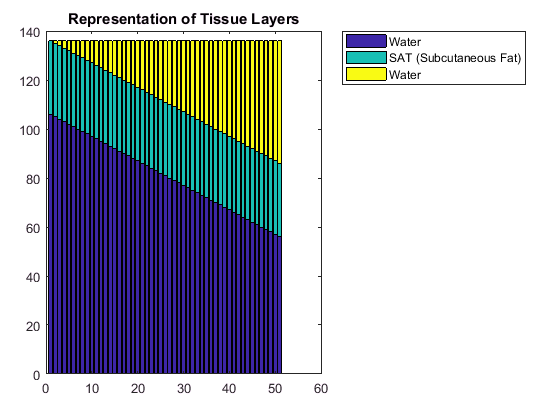

bodyLayer = {
    'Water', 0.0;
    'SAT (Subcutaneous Fat)', 30.0;
    'Water', 106.0;
    }; % mm

% Submerging the chicken under the water
for i=1:51
    bodyLayerMoving(:,i) = cell2mat(bodyLayer(:,2));
    bodyLayerMoving(1,i) = bodyLayerMoving(1,i) + (i-1);
    bodyLayerMoving(3,i) = bodyLayerMoving(3,i) - (i-1);
end

% Draw a dielectric layer model from order
bar(fliplr(bodyLayerMoving'),'stacked');
legend(flipud(bodyLayer(:,1)),'Location','northeastoutside')
title('Representation of Tissue Layers')
zlabel('Depth (mm)')

clear ph i;

## 3. Calculating the overall reflection response

n - Cole Cole Dispersions frequencies (Water has 2)

[http://vosykazoran.weebly.com/uploads/1/2/4/5/12453032/cole_cole_1941.pdf](http://vosykazoran.weebly.com/uploads/1/2/4/5/12453032/cole_cole_1941.pdf)

Time Constant Values 

[http://www.m-hikari.com/astp/astp2008/astp13-16-2008/thakurASTP13-16-2008.pdf](http://www.m-hikari.com/astp/astp2008/astp13-16-2008/thakurASTP13-16-2008.pdf)

Electrical Properties of tissues

[http://andrewamarino.com/PDFs/MB/MB_Ch06.pdf](http://andrewamarino.com/PDFs/MB/MB_Ch06.pdf)

**Cole Cole Dispersions**


$$\varepsilon \left(\omega \right)=\varepsilon_{\infty } +\sum_{m=1}^{n} \frac{\Delta \varepsilon_m }{1+{\left(j\omega \tau_m \right)}^{\left(1-\alpha_m \right)} }+\frac{\sigma_i }{j\omega \varepsilon_0 }$$


## Reflection Responses


$$\Gamma_i \left(\omega \right)=\frac{\rho_i +\Gamma_{i+1} e^{-2{\mathrm{jk}}_i l_i } }{1+\rho_i e^{-2{\mathrm{jk}}_i l_i } }$$



$$\rho_i =\frac{1-\sqrt{\frac{\varepsilon_i }{\varepsilon_{i-1} }}}{1+\sqrt{\frac{\varepsilon_i }{\varepsilon_{i-1} }}}$$


where $\Gamma_i$ is the reflection reponse at the ith interface. Initialized by  $\Gamma_{m+1} =\rho_{m+1}$.

 $l_i$ is the thickness

${\text{k}}_i \left(\varepsilon ',\varepsilon \mathrm{''}\right)$is the propogation parameter (real and imaginary)

$n=\sqrt{\varepsilon_r \mu_r }$  the refractive index. However $\mu_r$ is close to 1

$k=\frac{2\pi n}{\lambda_0 }$ the propogation parameter

Relationship betwen refractive index and permittivity

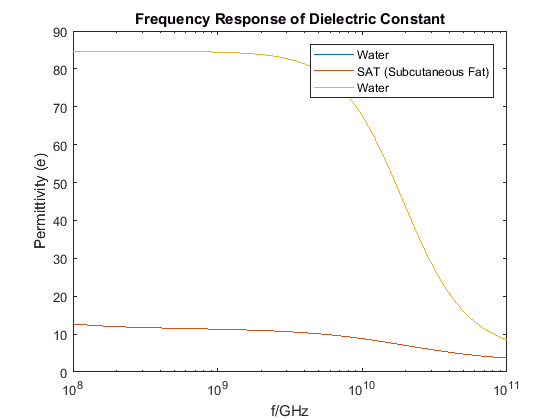

layer_count = length(bodyLayer);
fr = logspace(8,11);
e_w = zeros(layer_count+2, 50);
gamma = zeros(layer_count+1, 50);
f_test = zeros(layer_count+1, 50);

% Obtain frequency respones for all materials
for i = 1:layer_count
    materialName = bodyLayer{i, 1};
    [p_inf, p_del, t_const, a, con] = get_material(materialName);
    e_w(i+1,:) = create_material(p_inf, p_del, t_const, a, con);
    
    semilogx(fr, real(e_w(i+1,:)));
    hold on;
end
hold off;
title('Frequency Response of Dielectric Constant');
xlabel('f/GHz');
ylabel('Permittivity (e)');
legend(bodyLayer{:, 1});

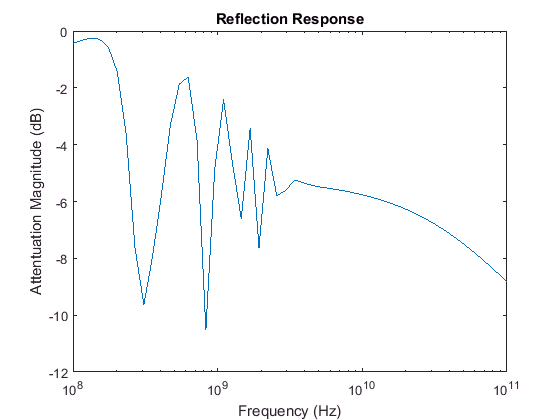


% First and last material is air
[p_inf, p_del, t_const, a, con] = get_material('Air');
e_w(1,:) = create_material(p_inf, p_del, t_const, a, con);
e_w(layer_count + 2,:) = e_w(1,:);

% Getting p
for i=1:layer_count+1
    f_test(i,:) = (1 - sqrt(e_w(i+1,:) ./ e_w(i,:))) ./ (1 + sqrt(e_w(i+1,:) ./ e_w(i,:)));
end

% Getting the refractive indexes and propogation constant (varies with frequency and layer)
n = e_w .^(0.5);
lambda = 3e8 ./ fr;
k = zeros(layer_count+2, 50);
for i = 1:length(n)
   k(:,i) = 2*pi*n(:, i) ./ lambda(i);
end

% Initialize del and p and then calculate gamma
gamma(layer_count+1,:) = f_test(layer_count+1,:);
l = cell2mat(bodyLayer(:, 2)) .* 1e-3; % Thickness of the layer
for i = layer_count:-1:1
    exponent = exp(-2i*k(i,:).*l(i));
    gamma(i,:) = (f_test(i,:) + gamma(i+1,:).*exponent) ./ (1 + f_test(i,:).*gamma(i+1,:).*exponent);
end

semilogx(fr, mag2db(abs(gamma(1,:))));
title('Reflection Response');
xlabel('Frequency (Hz)');
ylabel('Attentuation Magnitude (dB)');


clear i l k layer_count materialName p p_del t_const n p_inf con a exponent

## 4. Computing Measured signal using the reflection Responses 

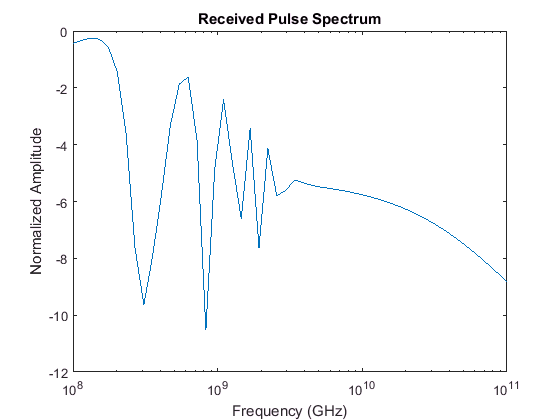

% Interpolation Filter
% gamma_zero = ones(1,length(gamma(1,:)));
c = 3e8;
r = 0.234; % Distance to the water
relect = gamma(1,:).*exp(-2j*center_freq*r/c);
[S_rx, s_rx] = interpolation_filter(S_tx, f, relect, fr);

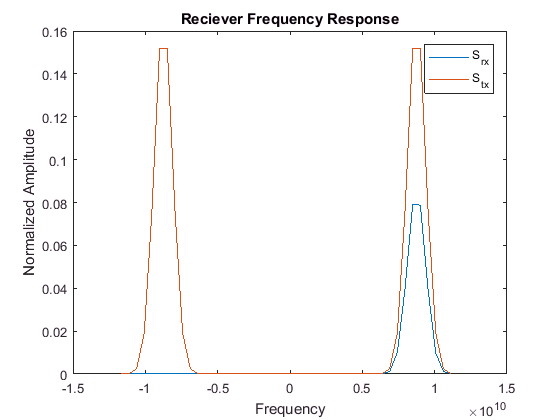


% Frequency Plot of the Transmitted and Recieved pulses
plot(f, abs(S_rx)./2);
hold on;
plot(f, abs(S_tx));
title('Reciever Frequency Response')
xlabel('Frequency')
ylabel('Normalized Amplitude')
legend('S_{rx}', 'S_{tx}');
hold off;


% Time Plot of the Transmitted and Recieved Pulses
% Note respond pulse is much smaller. Distance loss not accounted
delay = r/c*2;
plot(t, s_tx);
hold on;
plot(t+delay, s_rx);

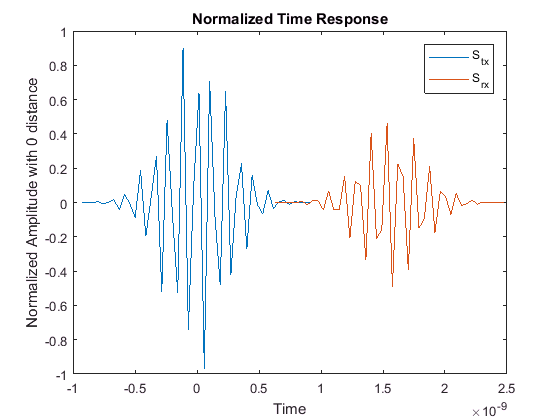

title('Normalized Time Response')
xlabel('Time')
ylabel('Normalized Amplitude with 0 distance')
legend('S_{tx}', 'S_{rx}');
hold off;

## 5. Power Losses and Time Delays

**Time Delays**


$$\tau =\frac{1}{c_0 }\sum_{i=1}^{14} l_i \sqrt{{\varepsilon '}_i }$$


**Power Losses**


$$P\left(y\right)=P\left(0\right)e^{-2\alpha y}$$



$$\alpha =\mathrm{Re}\left\lbrace \omega \sqrt{\mu_i \left({\varepsilon '}_i \left(\omega \right)-j{\varepsilon \mathrm{''}}_i \left(\omega \right)\right)}\right\rbrace$$



$$A_n /\mathrm{dB}=-20{\mathrm{log}}_{10} \left(e\right)\cdot \sum_{i=1}^{n} \alpha_i \cdot \Delta y_i$$


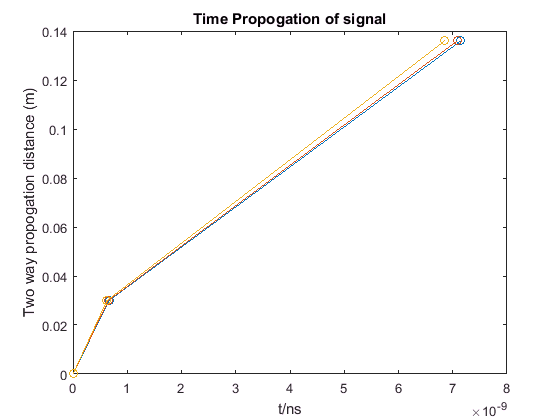

% Time delay
c = 3e8;
tao = real(e_w(2:end-1,:)).^0.5;
l = cell2mat(bodyLayer(:,2))*1e-3;
for i=1:length(l)
   tao(i,:) = tao(i,:) * l(i) / c;
end
tao_cum = cumsum(tao)*2; % 2 times for 2 way propogation
l_cum = cumsum(l);
plot(tao_cum(:,20), l_cum, 'Marker', 'o');
hold on;
plot(tao_cum(:,25), l_cum, 'Marker', 'o');
plot(tao_cum(:,30), l_cum, 'Marker', 'o');
title('Time Propogation of signal')
xlabel('t/ns')
ylabel('Two way propogation distance (m)')
hold off;

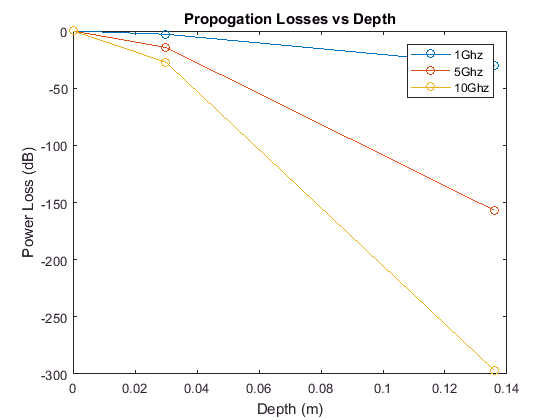


% Power Losses
e0 = 8.85e-12;
u0 = 1.256e-6;
alpha = real(fr.*sqrt(e0*u0*(real(e_w(2:end-1,:)) - 1j*imag(e_w(2:end-1,:)))));

An = zeros(length(e_w), length(l));
for i = 1:length(l)
    An(:,i) = alpha(i, :) .* l(i);
    if i >= 2
        An(:,i) = An(:,i) + An(:,i-1);
    end
end

An = An * -20 * log10(exp(1));

for i = [17,29,34]
    plot(l_cum, An(i,:), 'Marker', 'o');
    hold on;
end
hold off;

title('Propogation Losses vs Depth')
xlabel('Depth (m)')
ylabel('Power Loss (dB)')
legend('1Ghz','5Ghz','10Ghz')


clear len tmp

## 6. Signal Response Estimation 

See the link below. The image shows why the energy loss is still 1/r^2

[http://www.eetimes.com/document.asp?doc_id=1274793](http://www.eetimes.com/document.asp?doc_id=1274793)


$$\frac{E_{\mathrm{Rx}} }{E_{\mathrm{Tx}} }\left(\omega \right)=\Gamma \left(\omega \right)\left\lbrack d\left(r\right)\mathrm{exp}\left(-2j\frac{\omega }{c_0 }r\right)\right\rbrack$$


with a varying r, we have a variable recieved pulse with a time delay, which will lead to a shifted correlation coefficient Rxy


$$d\left(r\right)=\frac{P_{\mathrm{Rx}} }{P_{\mathrm{Tx}} }=\frac{l^2 }{{\left(8\mathrm{rsin}\theta +l\right)}^2 }$$


where l is length of the patch,r is the single distance between the sender and reciever. This is only an approximation

gamma = {}


gamma =

  0×0 empty cell array



% Getting a difference response becuase of the different depth
for i = 1:51
    [gamma{i}, ~, ~] = multidielsweep(bodyLayer, bodyLayerMoving(:,i));
end

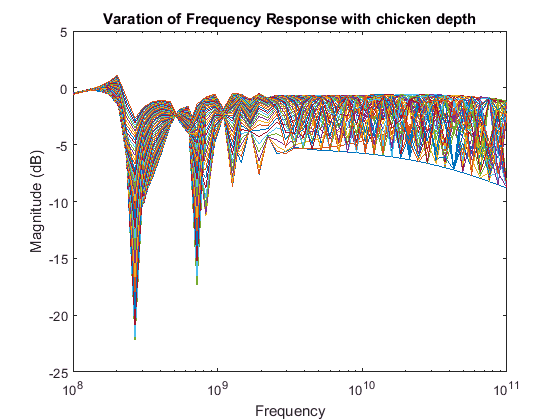

% Plotting the frequency function Difference
testfreqs = 1:51;
for i = testfreqs
   semilogx(fr, mag2db(abs(gamma{i}(1,:)))); 
   hold on;
end
title('Varation of Frequency Response with chicken depth')
xlabel('Frequency')
ylabel('Magnitude (dB)')
hold off;

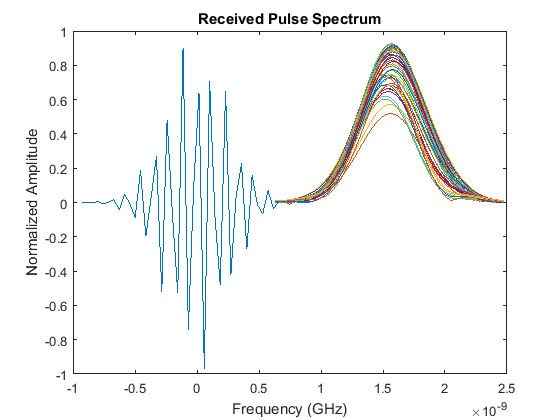


% Plotting the time response difference
c = 3e8;
r = 0.234; % Distance to the water

% Tx Signal
delay = r/c*2;
plot(t, s_tx);
hold on;
for i = testfreqs
    relect = gamma{i}(1,:).*exp(-2j*center_freq*r/c);
    [~, s_rx(i,:)] = interpolation_filter(S_tx, f, relect, fr);
    
    plot(t+delay, abs(s_rx(i,:)));
end
hold off;

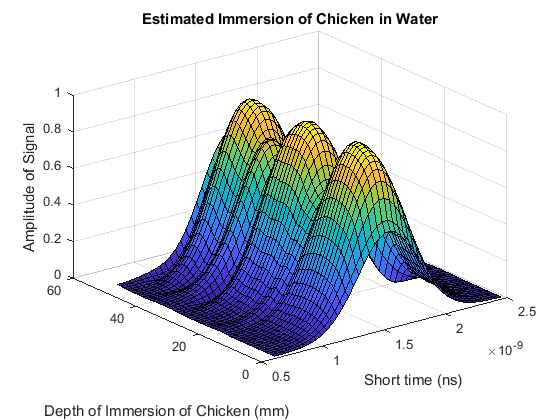


surf(t+delay,testfreqs, abs(s_rx));
title('Estimated Immersion of Chicken in Water')
xlabel('Short time (ns)')
ylabel('Depth of Immersion of Chicken (mm)')
zlabel('Amplitude of Signal')

## 6. Calculating Covariance Matrices

Q the covariance matrix, is calculated from the cross correlation Rxy


$$Q=\frac{1}{N-1}R_{\mathrm{xy}} {R_{\mathrm{xy}} }^T$$


Rxy is calculated from the transmitted and received signals


$$R_{\mathrm{xy}} \left(\tau \right)=\int S_{T_x } \left(t+\tau \right)S_{R_x } \left(t\right)\mathrm{dt}$$



$$=S_{T_x } \left(-\tau \right)\circ S_{R_x } \left(\tau \right)=S_{T_x } \left(-\tau \right)\circ S_{R_x } \left(\tau \right)$$


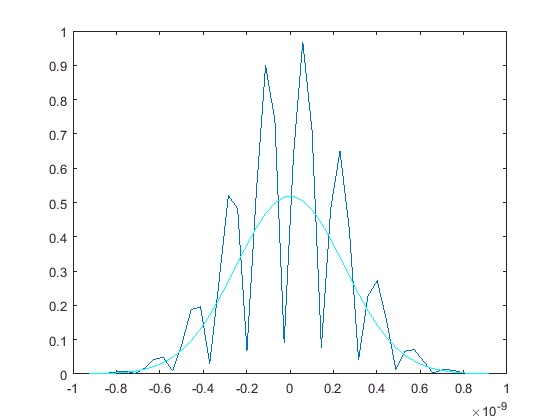

Rxy = corr(s_tx, s_rx(1,:));
Rxy_t = -(length(Rxy)/2)/Fs:1/Fs:(length(Rxy)/2-1)/Fs;
plot(Rxy_t, real(Rxy), 'black');
hold on;
plot(t, abs(s_tx));
plot(t, abs(s_rx(1,:)),'cyan');


% Not done yet
